# 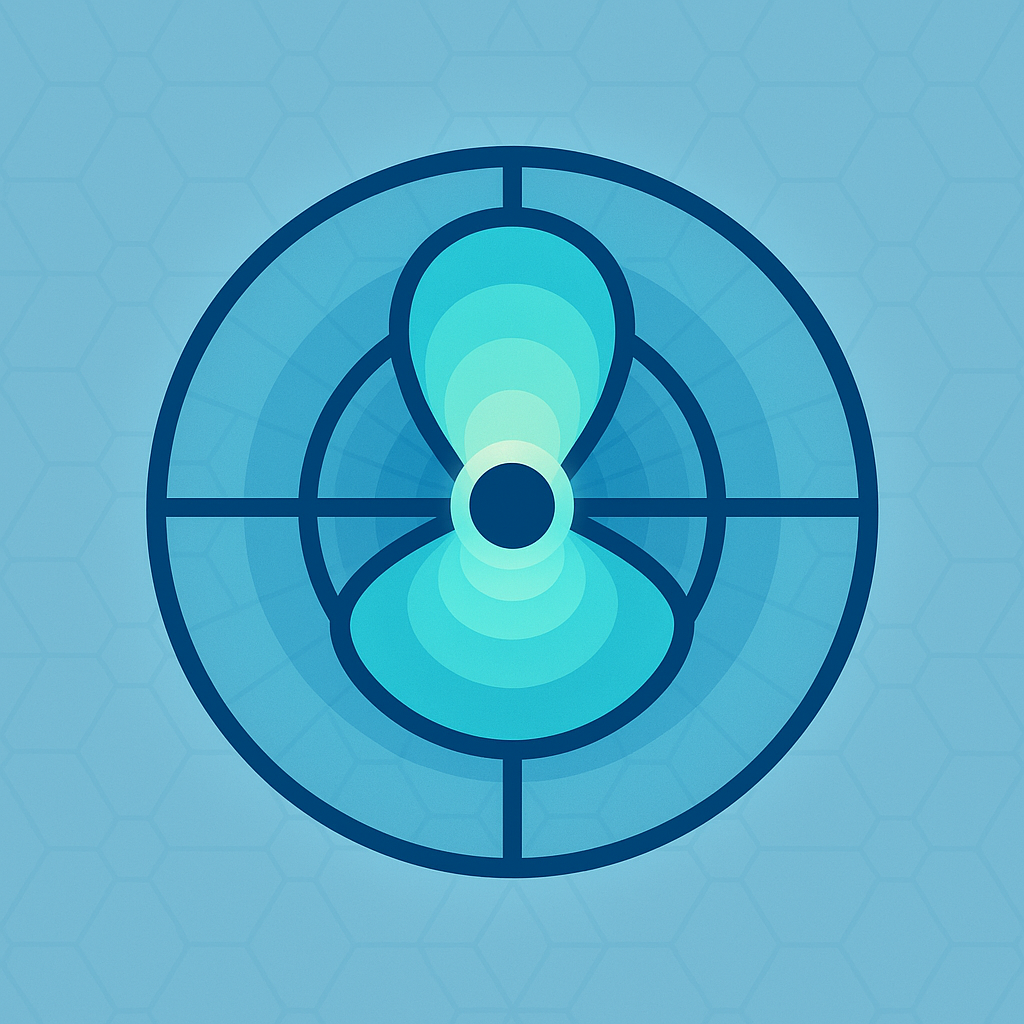 SHG Plotting and Analyze 

*Xinchuan Du*, Update: 2025-10-17

This script loads polarization-dependent SHG measurement data (.mat), extracts the intensity near the SHG peak, normalizes and averages over two half-wave-plate rotation cycles, and visualizes the results in both polar and Cartesian coordinates. A nonlinear least-squares fit is then performed based on the squared SHG intensity model:


$$\[
I(\theta) = \left[ 
A_1 \cos\!\big(3(\theta - \theta_0)\big)
+ A_2 \cos\!\big(\theta - \theta_0\big)
- A_3 \sin\!\big(\theta - \theta_0\big)
\right]^2
\]
$$


The script outputs fitted parameters (A1, A2, A3, θ₀) and quantitative metrics (R², RMSE), and provides a manual fit preview section for quick parameter tuning and comparison.

## **STEP 1: Data Loading**

Import the `.mat` file exported from **WITec Project**, which contains the **Analyzer Series data** acquired from WITec SHG measurements.

This step loads the polarization-resolved spectral dataset into the script for subsequent analysis.

clear; clc;
warning('off','all');
load("D:\NUS Dropbox\Xinchuan Du\PendingPrj\Publication\MoS2 in-plane electrostriction\Data\Raman\Series Ana--4521--Spec.Data 1_SHG_3.mat");
warning('on','all');

## **STEP 2: Data Visualization**

Generate both polar and Cartesian plots based on the measured data to inspect the SHG polarization characteristics.

The integration center, integration bandwidth, and smoothing parameters can be adjusted to fine-tune the extracted SHG intensity profile.

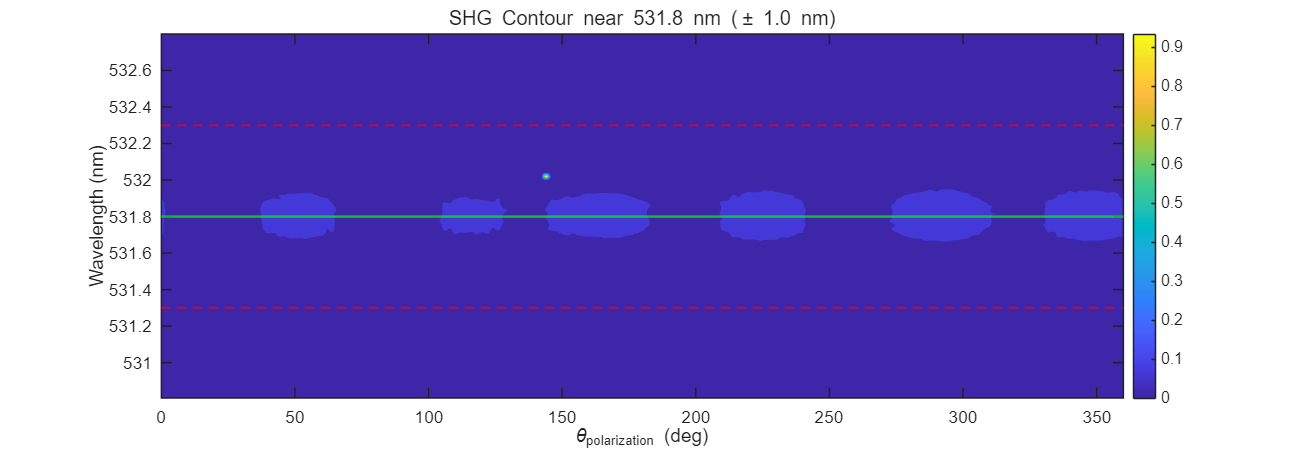

% === Minimal SHG Polar Plot (0–360°, correct for index-type axis) ===

center_nm   = 531.8;   % SHG center wavelength
int_half_nm = 0.5;     % integration ± window
smooth_win  = 5;       % smoothing window
enable_contour = true;
if exist('S','var')
    clear S s
end
s = whos; S = eval(s(strcmp({s.class},'struct')).name);
D = double(S.data);
lambda = S.axisscale{2};       % wavelength axis
N = size(D,1);

% --- Real angles ---
theta_hwp = linspace(0,360,N)';   % HWP rotation (0–360°)
theta_pol = 2 * theta_hwp;        % polarization rotation (0–720°)

% --- Integrate near SHG peak ---
[~,idx] = min(abs(lambda - center_nm));
mask = abs(lambda - lambda(idx)) <= int_half_nm;
I = mean(D(:,mask),2,'omitnan');
if smooth_win>1, I = movmean(I,smooth_win,'Endpoints','shrink'); end
I = I - min(I); I = I./max(I);

% --- Split into two 0–360° cycles ---
half = floor(N/2);
th1 = theta_pol(1:half);
th2 = theta_pol(half+1:end) - 360;   % wrap to 0–360
I1 = I(1:half);
I2 = I(half+1:end);

% --- Interpolate to common grid and average ---
theta_common = linspace(0,360,361);
I1i = interp1(th1,I1,theta_common,'linear','extrap');
I2i = interp1(th2,I2,theta_common,'linear','extrap');
Iavg = (I1i + I2i)/2;
Iavg = Iavg - min(Iavg); Iavg = Iavg./max(Iavg);

%% ===== Option: Enable SHG Contour Map =====
contour_half_nm  = int_half_nm * 2; % Wavelength window (±) for contour display
contour_levels   = 14;             % Number of contour levels

if enable_contour
    % --- Rewrap two 0–360° cycles into one continuous cycle ---
    half = floor(N/2);
    theta_0_360 = [theta_pol(1:half); ...
                   theta_pol(half+1:end) - 360];   % wrap second cycle
    D_rewrap = [D(1:half,:); D(half+1:end,:)];     % rearrange data accordingly

    % --- Select wavelength window around SHG center ---
    mask_c = abs(lambda - center_nm) <= contour_half_nm;
    L = lambda(mask_c);             % wavelength axis within window
    Z = D_rewrap(:, mask_c);        % intensity matrix [angle_steps × lambda_window]

    % --- Merge 360° to 0° to avoid duplicate sample points ---
    theta_0_360(theta_0_360 == 360) = 0;

    % --- Remove duplicate angles and average intensity (column-wise) ---
    [theta_u, ~, ic] = unique(theta_0_360(:));
    Zu = zeros(numel(theta_u), size(Z,2));
    for j = 1:size(Z,2)
        Zu(:,j) = accumarray(ic, Z(:,j), [], @(v) mean(v,'omitnan'));
    end
    [theta_u, order] = sort(theta_u);
    Zu = Zu(order, :);

    % --- Interpolate to uniform angular grid ---
    theta_grid = linspace(0,360,721);  % 0.5° resolution
    Z_i = interp1(theta_u, Zu, theta_grid, 'pchip', 'extrap');  % [θ × λ]

    % --- Normalize for visualization ---
    Z_i = Z_i - min(Z_i(:));
    if max(Z_i(:)) > 0
        Z_i = Z_i ./ max(Z_i(:));
    end

    % ================== Contour Plot ==================
    figure('Color','w','Position',[100 100 1300 450]);  % keep same aspect ratio
    contourf(theta_grid, L, Z_i', contour_levels, 'LineColor','none');
    set(gca,'YDir','normal','FontSize',13,'LineWidth',1.1);
    colormap parula; colorbar;

    xlabel('\theta_{polarization} (deg)','FontSize',14);
    ylabel('Wavelength (nm)','FontSize',14);
    title(sprintf('SHG Contour near %.1f nm (\\pm %.1f nm)', ...
          center_nm, contour_half_nm), ...
          'FontWeight','normal','FontSize',15);
    xlim([0 360]);

    % --- Mark integration window (±int_half_nm) with red dashed lines ---
    hold on;
    yline(center_nm - int_half_nm, 'r--', 'LineWidth', 1.5, ...
           'DisplayName', sprintf('Integration window ±%.1f nm', int_half_nm));
    yline(center_nm + int_half_nm, 'r--', 'LineWidth', 1.5, 'HandleVisibility','off');

    % --- Mark SHG center wavelength with a green solid line ---
    yline(center_nm, 'g-', 'LineWidth', 1.8, ...
           'DisplayName', sprintf('Center wavelength %.1f nm', center_nm));
    hold off;
end

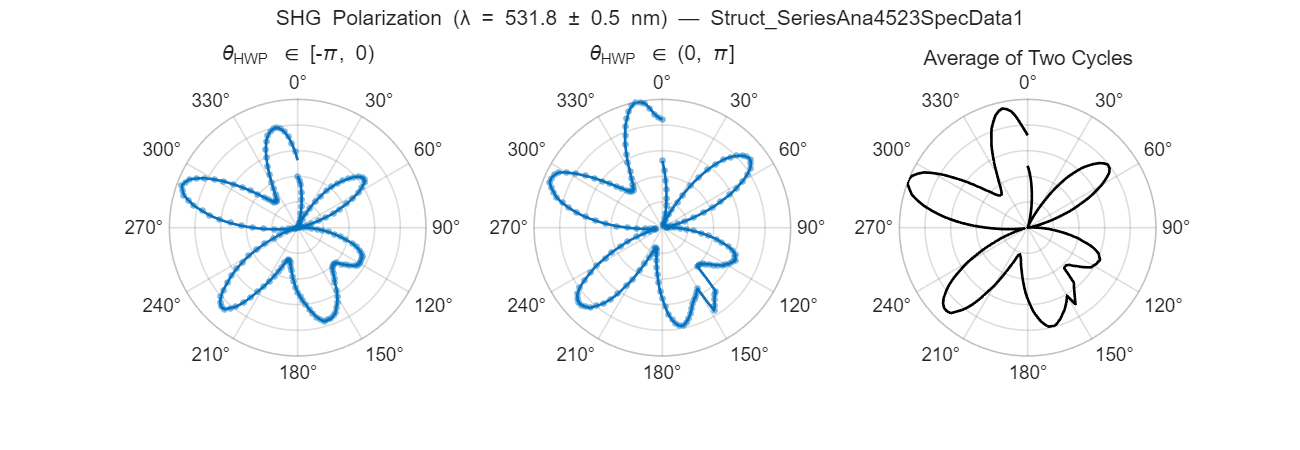




%% ================== Polar plots ==================
figure('Color','w','Position',[100 100 1300 450]);

subplot(1,3,1);
polarplot(deg2rad(theta_common), I1i, 'LineWidth', 2); hold on;
scatter(deg2rad(th1), I1, 25, ...
    'filled', 'MarkerFaceColor', [0 0.447 0.741], 'MarkerFaceAlpha', 0.5);
title('\theta_{HWP} \in [-\pi, 0)', 'FontWeight', 'normal');
set(gca,'ThetaZeroLocation','top','ThetaDir','clockwise', ...
    'RTickLabel',[],'FontSize',14,'LineWidth',1.2);

subplot(1,3,2);
polarplot(deg2rad(theta_common), I2i, 'LineWidth', 2); hold on;
scatter(deg2rad(th2), I2, 25, ...
    'filled', 'MarkerFaceColor', [0 0.447 0.741], 'MarkerFaceAlpha', 0.5);
title('\theta_{HWP} \in (0, \pi]', 'FontWeight', 'normal');
set(gca,'ThetaZeroLocation','top','ThetaDir','clockwise', ...
    'RTickLabel',[],'FontSize',14,'LineWidth',1.2);

subplot(1,3,3);
polarplot(deg2rad(theta_common), Iavg, 'k','LineWidth', 2); hold on;
title('Average of Two Cycles', 'FontWeight', 'normal');
set(gca,'ThetaZeroLocation','top','ThetaDir','clockwise', ...
    'RTickLabel',[],'FontSize',14,'LineWidth',1.2);
sgtitle( ...
    sprintf('SHG Polarization (λ = %.1f ± %.1f nm) — %s', ...
    center_nm, int_half_nm, ...
    strrep(s(strcmp({s.class},'struct')).name, '_', '\_')), ...
    'FontSize',16);

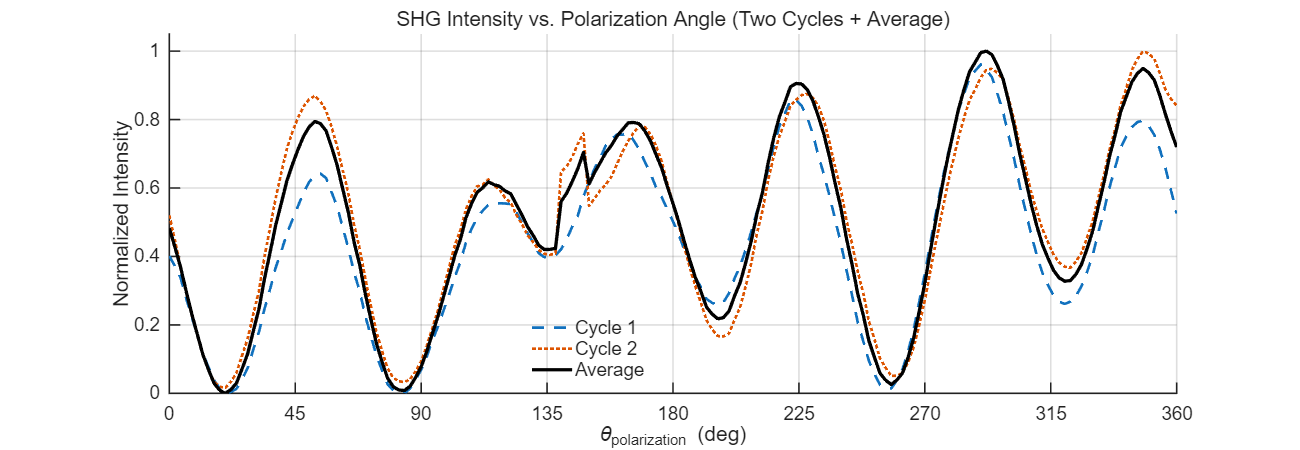

% ================== Linear plot ==================
figure('Color','w','Position',[100 100 1300 450]);
hold on;

plot(theta_common, I1i, '--', 'LineWidth', 2.0, 'DisplayName', 'Cycle 1');
plot(theta_common, I2i, ':',  'LineWidth', 2.0, 'DisplayName', 'Cycle 2');
plot(theta_common, Iavg, 'k-', 'LineWidth', 2.5, 'DisplayName', 'Average');

xlabel('\theta_{polarization} (deg)', 'FontSize', 16);
ylabel('Normalized Intensity', 'FontSize', 16);
xlim([0 360]); xticks(0:45:360);
ylim([0 1.05]); yticks(0:0.2:1);
grid on;hold off;

legend('show','Location','best','FontSize',14,'Box','off');
title('SHG Intensity vs. Polarization Angle (Two Cycles + Average)', ...
      'FontSize', 16, 'FontWeight', 'normal');
set(gca,'FontSize',14,'LineWidth',1.2);

## **STEP 3: Model Fitting**

Fit the measured polarization dependence using the stress-aware SHG model to extract the coefficients and the rotation angle. Parameter bounds can be specified to ensure physically meaningful solutions.

#### **Model: **$\[
I(\theta) = \left[ 
A_1 \cos\!\big(3(\theta - \theta_0)\big)
+ A_2 \cos\!\big(\theta - \theta_0\big)
- A_3 \sin\!\big(\theta - \theta_0\big)
\right]^2
\]
$

#### **Parameter meaning**

- **A1�** — overall SHG amplitude (signal strength).

- **A2****�** — contribution associated with **biaxial (isotropic) stress**.

- **A3****�** — contribution associated with **shear stress**.

- **θ0****�** — rotation phase capturing **crystal/structure orientation** relative to the polarization reference.

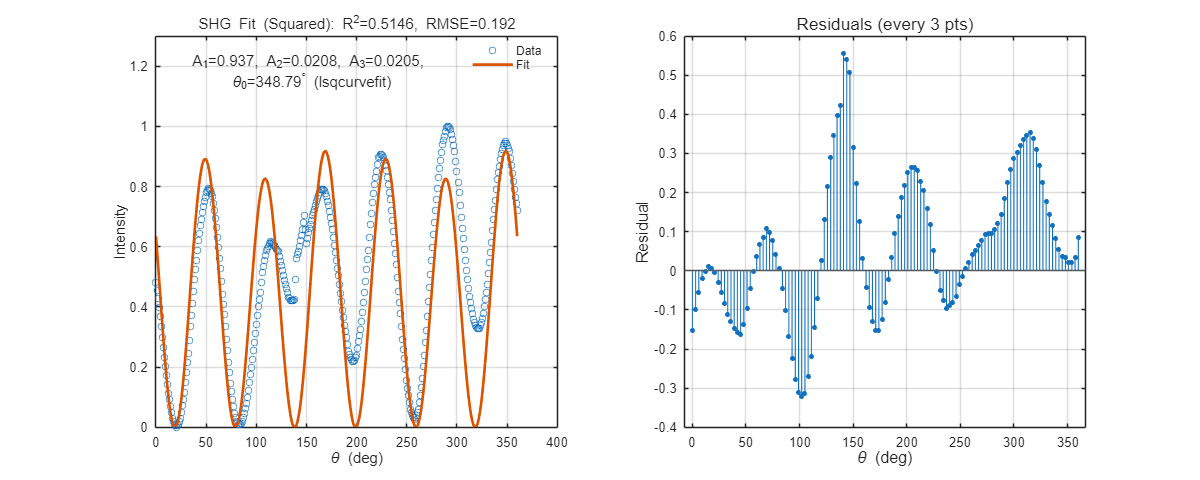

theta_deg = theta_common(:);
I         = Iavg(:);
theta_rad = deg2rad(theta_deg);
A1_range = [0 2];
A2_range = [-0.2 0.2];
A3_range = [-0.2 0.2];
% ===== 选项 =====
use_normalize = false;     % 是否零均值中心化强度
show_plots    = true;     % 是否绘图
show_iter     = 'off';    % 'off' 或 'iter'（控制优化器的过程显示）

% ===== 初值与边界（可修改）=====
% 参数顺序: [A1, A2, A3, theta0(rad)]
initialParams = [1.0, 1.0, 1.0, deg2rad(0)];      % 初值
lb            = [A1_range(1), A2_range(1), A3_range(1), -pi];            % 下界（例：theta0 ∈ [0, 2π]）
ub            = [A1_range(2), A2_range(2), A3_range(2), pi];         % 上界
% 例如固定 theta0=45°：把 lb(4)=ub(4)=deg2rad(45)

% ===== 预处理 =====
if use_normalize
    I_mean = mean(I);
    Iy = I - I_mean;
else
    I_mean = 0;
    Iy = I;
end

% ===== 模型（平方形式）=====
% I(theta) = [A1*cos(3*(theta - theta0)) + A2*cos(theta - theta0) - A3*sin(theta - theta0)]^2
fitFunc = @(p, th) ( p(1).*cos(3*(th - p(4))) + ...
                     p(2).*cos(   (th - p(4))) - ...
                     p(3).*sin(   (th - p(4))) ).^2;

% ===== 选择带"边界"的求解器；若不可用则自动回退 =====
solver_used = '';
p_opt = initialParams;
Ifit  = [];

if exist('lsqcurvefit','file') == 2
    % 优先 lsqcurvefit（非线性最小二乘，天然支持边界）
    opts = optimoptions('lsqcurvefit','Display',show_iter, ...
                        'MaxFunctionEvaluations',5e4,'MaxIterations',2e3);
    [p_opt, ~, ~, exitflag] = lsqcurvefit(fitFunc, initialParams, theta_rad, Iy, lb, ub, opts); %#ok<ASGLU>
    solver_used = 'lsqcurvefit';
elseif exist('fmincon','file') == 2
    % 次选 fmincon（通用有界优化，目标为 SSE）
    obj = @(p) sum((Iy - fitFunc(p, theta_rad)).^2);
    opts = optimoptions('fmincon','Display',show_iter, ...
                        'MaxFunctionEvaluations',5e4,'MaxIterations',2e3, ...
                        'SpecifyObjectiveGradient','off','Algorithm','interior-point');
    [p_opt, ~, exitflag] = fmincon(obj, initialParams, [],[],[],[], lb, ub, [], opts); %#ok<ASGLU>
    solver_used = 'fmincon';
else
    % 回退 fminsearch（无边界）：采用"投影 + 惩罚"的目标函数近似边界
    proj = @(p) min(max(p, lb), ub);              % 投影到边界内
    penalty = @(p) 1e6 * sum((p < lb | p > ub) .* (abs(p - min(max(p,lb),ub)).^2));
    obj = @(p) ( ...
        sum((Iy - fitFunc(proj(p), theta_rad)).^2) + penalty(p) ...
    );
    opts = optimset('Display',show_iter,'MaxFunEvals',5e4,'MaxIter',2e3);
    p_opt = fminsearch(obj, initialParams, opts);
    p_opt = proj(p_opt);
    solver_used = 'fminsearch+projection';
end

% 规范相位到 [0, 2π]
p_opt(4) = mod(p_opt(4), 2*pi);

% ===== 结果与评估 =====
Ifit = fitFunc(p_opt, theta_rad) + I_mean;
sse  = sum((I - Ifit).^2);
sst  = sum((I - mean(I)).^2);
R2   = 1 - sse/sst;
RMSE = sqrt(mean((I - Ifit).^2));

% 拟合参数与指标（存在变量中，不打印）
A1 = p_opt(1); A2 = p_opt(2); A3 = p_opt(3); theta0_deg = rad2deg(p_opt(4));
% 现在工作区可直接查看：A1, A2, A3, theta0_deg, R2, RMSE, solver_used
% 如需固定某参数：把对应 lb=ub=该值 即可

% ===== 绘图 =====
if show_plots
    figure('Color','w','Position',[100 100 1200 480]);

    % 数据与拟合曲线
    subplot(1,2,1);
    plot(theta_deg, I, 'o', 'MarkerSize', 5, 'DisplayName', 'Data'); hold on;
    plot(theta_deg, Ifit, '-', 'LineWidth', 2, 'DisplayName', 'Fit');
    xlabel('\theta (deg)'); ylabel('Intensity');ylim([0,1.3])
    grid on; legend('show','Location','best','Box','off');
    title(sprintf('SHG Fit (Squared): R^2=%.4f, RMSE=%.3g', R2, RMSE), 'FontWeight','normal');

    %% ===== 残差绘图（稀疏显示）=====
    skip = 3;  % 抽样间隔，比如 3 表示每隔 3 个点画一个
    idx = 1:skip:numel(theta_deg);
    
    subplot(1,2,2);
    stem(theta_deg(idx), I(idx)-Ifit(idx), 'filled', ...
        'MarkerSize', 3, ...
        'LineWidth', 0.8, ...
        'DisplayName', 'Residuals');
    hold on;
    yline(0,'-','LineWidth',0.6,'Color',[0.4 0.4 0.4]);
    grid on;
    
    xlabel('\theta (deg)','FontSize',12);
    ylabel('Residual','FontSize',12);
    title(sprintf('Residuals (every %d pts)', skip), ...
        'FontWeight','normal','FontSize',13);

    % 可选参数注释（不占用命令行）
    txt = sprintf('A_1=%.3g, A_2=%.3g, A_3=%.3g, \n\\theta_0=%.2f^\\circ (%s)', ...
        A1, A2, A3, theta0_deg, solver_used);
    annotation('textbox',[0.11 0.78 0.3 0.12],'String',txt, ...
        'EdgeColor','none','HorizontalAlignment','center','FontSize',11);
end

ResultTable = table(A1, A2, A3, theta0_deg, R2, RMSE, ...
    'VariableNames', {'A1', 'A2', 'A3', 'Theta0_deg', 'R2', 'RMSE'})

ResultTable = 1×6 table
      A1         A2          A3       Theta0_deg      R2        RMSE  
    _______    _______    ________    __________    _______    _______

    0.93709    0.02084    0.020522      348.79      0.51456    0.19187


## STEP 4: Manual Fitting

Manually adjust the parameters A1�, A2�, A3�, and θ0 to intuitively examine how each term affects the SHG polarization response. The script recalculates and plots the fitted curve together with the measured data, allowing quick visual comparison and basic evaluation (R², RMSE) without running the full optimization.

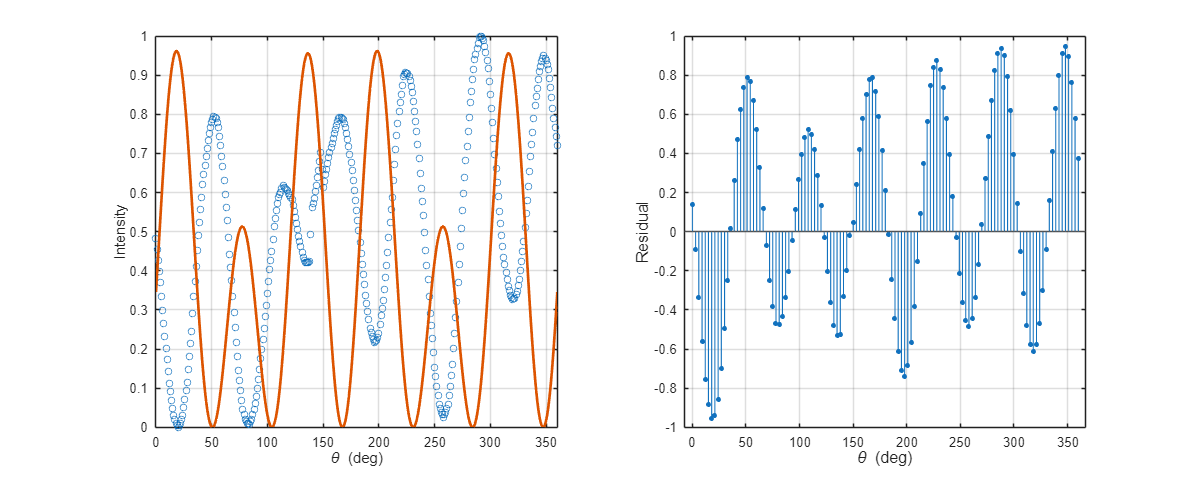

%% ===== Manual SHG Fit Preview (Squared Model) =====
% 依赖变量：theta_common (deg), Iavg
% 只需改动下面四个值即可
A1 = 0.8907641712239941;            % 幅值系数: cos(3*(θ-θ0))
A2 = 0.08865783744117796;            % 幅值系数: cos(   (θ-θ0))
A3 = -0.15;            % 幅值系数: sin(   (θ-θ0)) [注意模型里是减号]
theta0_deg = 17.33445089381551;      % 相位 (degree)
enable_evaluate = true;   % Toggle: true = compute and display fit metrics

% ---------- 计算与绘图 ----------
theta_deg = theta_common(:);
theta_rad = deg2rad(theta_deg);
I = Iavg(:);

Ifit = ( A1.*cos(3*(theta_rad - deg2rad(theta0_deg))) ...
       + A2.*cos(   (theta_rad - deg2rad(theta0_deg))) ...
       - A3.*sin(   (theta_rad - deg2rad(theta0_deg))) ).^2;

figure('Color','w','Position',[100 100 1200 480]);

subplot(1,2,1);  % 数据 vs 手动参数曲线
plot(theta_deg, I, 'o', 'MarkerSize', 5, 'DisplayName', 'Data'); hold on;
plot(theta_deg, Ifit, '-', 'LineWidth', 2, 'DisplayName', 'Manual Curve');
xlabel('\theta (deg)'); ylabel('Intensity'); xlim([0, 360]);grid on;

skip = 3;  % 抽样间隔，比如 3 表示每隔 3 个点画一个
idx = 1:skip:numel(theta_deg);

subplot(1,2,2);
stem(theta_deg(idx), I(idx)-Ifit(idx), 'filled', ...
    'MarkerSize', 3, ...
    'LineWidth', 0.8, ...
    'DisplayName', 'Residuals');
hold on;
yline(0,'-','LineWidth',0.6,'Color',[0.4 0.4 0.4]);
grid on;

xlabel('\theta (deg)','FontSize',12);
ylabel('Residual','FontSize',12);

%% ===== Option: Evaluate Fit Quality =====
if enable_evaluate
    % --- Compute evaluation metrics ---
    sse  = sum((I - Ifit).^2);
    sst  = sum((I - mean(I)).^2);
    R2   = 1 - sse/sst;
    RMSE = sqrt(mean((I - Ifit).^2));

    % --- Display results in a horizontal table ---
    MetricTable = table(sse, sst, R2, RMSE, ...
        'VariableNames', {'SSE', 'SST', 'R2', 'RMSE'})
end

MetricTable = 1×4 table
     SSE       SST        R2        RMSE  
    ______    ______    _______    _______

    103.59    27.378    -2.7835    0.53567
